# Práctica 1 - Cortocircuitos I - Apartado B

Cortocircuito simétrico (F30) en el punto F1 en función de x

## Sistemas Eléctricos y de Potencia

Subgrupo 10

format shortG
sympref('FloatingPointOutput', true);
if ~exist('Sbase', 'var')
    evalc('Practica1A');
end

## Cálculo del valor de la corriente de cortocircuito

### Paso 1: Circuito equivalente (en secuencia directa)

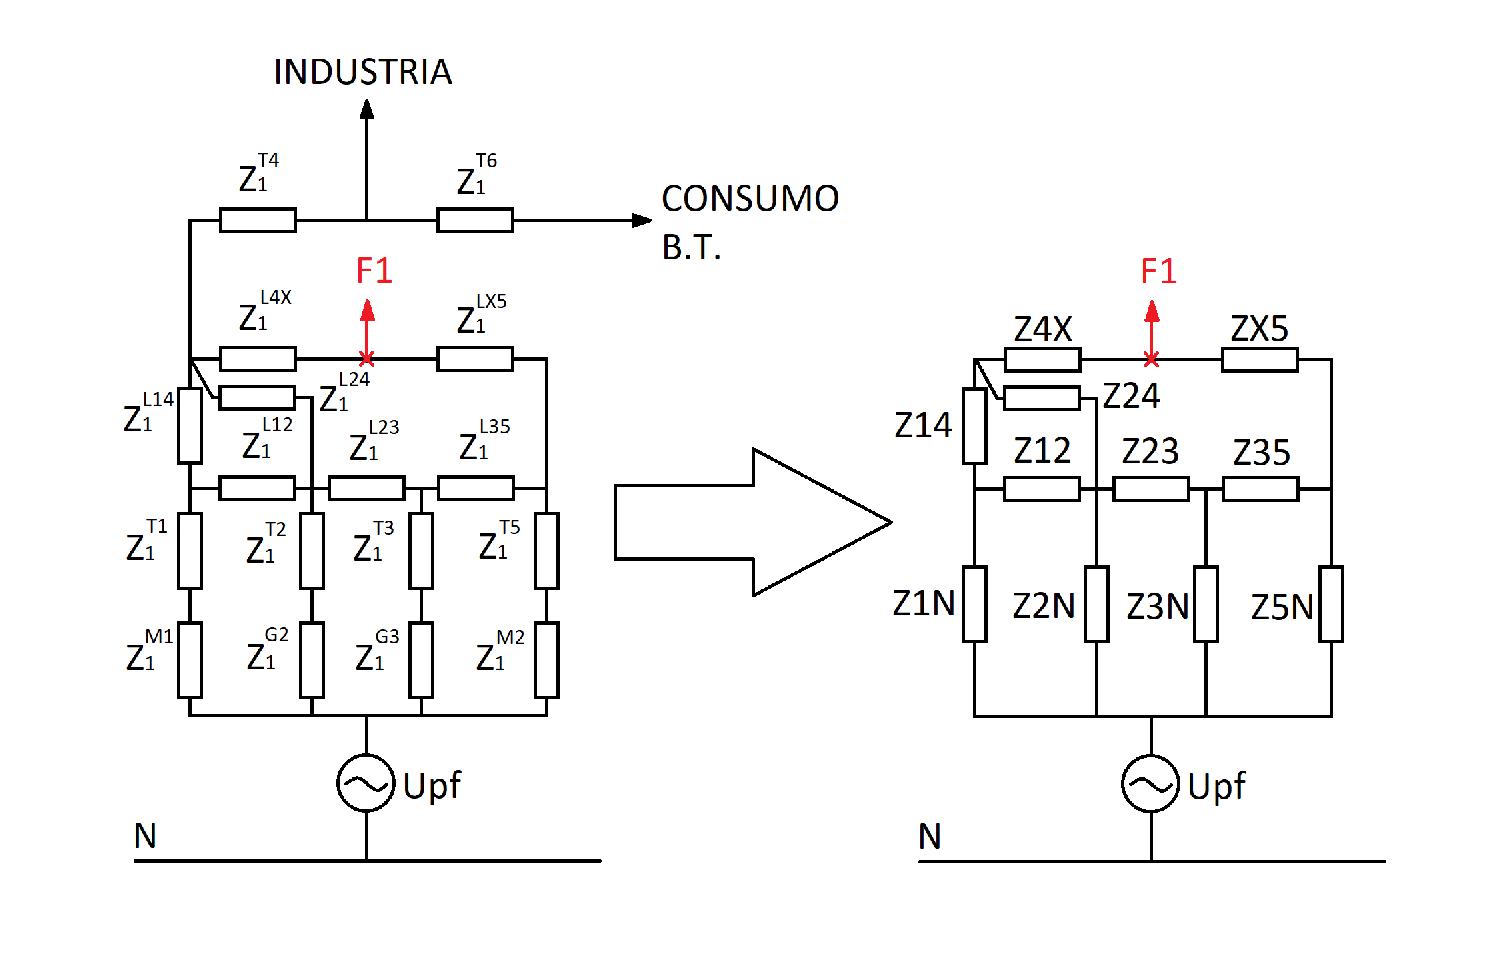

% Datos
Ubase_F1 = Ubase1;
Ibase_F1 = Sbase/(sqrt(3)*Ubase_F1);
Upf_F1 = 1.05;

% Valor de x (10% - 90%)
x_val =20;

imshow('F1_1.png');


% Valores de todas las impedancias iniciales
Z1N = ZT1pu(1) + ZM1pu(1);
Z12 = ZL12pu(1);
Z14 = ZL14pu(1);
Z2N = ZT2pu(1) + ZG2pu(1);
Z23 = ZL23pu(1);
Z24 = ZL24pu(1);
Z3N = ZT3pu(1) + ZG3pu(1);
Z35 = ZL35pu(1);
Z4F1 = ZL4Xpu(1);
Z5N = ZT5pu(1) + ZM2pu(1);
Z5F1 = ZL5Xpu(1);


### Paso 2: Triángulo-Estrella 1 (puntos 1, 2 y 4)

Se llama Y1 al centro de la nueva estrella

% Paso triángulo-estrella
[Z1Y1, Z2Y1, Z4Y1] = Triangle2Star(Z12, Z24, Z14)

Z1Y1 =             0 +   0.014998i


Z2Y1 =             0 +   0.021426i


Z4Y1 =             0 +   0.085706i



% Impedancias serie resultantes
ZF1Y1 = Z4Y1 + Z4F1

$$ZF1Y1 = 0.2296\,x\,\mathrm{i}+0.0857\,\mathrm{i}$$

ZNY1 = Z1Y1 + Z1N

ZNY1 =             0 +     1.5067i


### Paso 3: Triángulo-Estrella 2 (puntos 3, 5 y N)

Se llama Y2 al centro de la nueva estrella

% Paso triángulo-estrella
[Z3Y2, Z5Y2, ZNY2] = Triangle2Star(Z35, Z5N, Z3N)

Z3Y2 =             0 +   0.017601i


Z5Y2 =             0 +    0.19241i


ZNY2 =             0 +    0.17318i



% Impedancias serie resultantes
Z2Y2 = Z23 + Z3Y2

Z2Y2 =             0 +    0.09795i


ZF1Y2 = Z5F1 + Z5Y2

$$ZF1Y2 = -0.2296\,x\,\mathrm{i}+0.4220\,\mathrm{i}$$

### Paso 4: Triángulo-Estrella 3 (puntos 2, N e Y1)

Se llama Y3 al centro de la nueva estrella

% Paso triángulo-estrella
[Z2Y3, ZNY3, ZY1Y3] = Triangle2Star(Z2N, ZNY1, Z2Y1)

Z2Y3 =             0 +  0.0028558i


ZNY3 =             0 +    0.20082i


ZY1Y3 =             0 +    0.01831i



% Impedancias serie resultantes
ZF1Y3 = ZF1Y1 + ZY1Y3

$$ZF1Y3 = 0.2296\,x\,\mathrm{i}+0.1040\,\mathrm{i}$$

ZY2Y3 = Z2Y2 + Z2Y3

ZY2Y3 =             0 +    0.10081i


### Paso 5: Triángulo-Estrella 4 (puntos N, Y2 e Y3)

Se llama Y4 al centro de la nueva estrella

% Paso triángulo-estrella
[ZNY4, ZY2Y4, ZY3Y4] = Triangle2Star(ZNY2, ZY2Y3, ZNY3)

ZNY4 =             0 +   0.073246i


ZY2Y4 =             0 +   0.036767i


ZY3Y4 =             0 +   0.042636i



% Impedancias serie resultantes
ZF1Y4_1 = ZF1Y2 + ZY2Y4

$$ZF1Y4\_1 = -0.2296\,x\,\mathrm{i}+0.4587\,\mathrm{i}$$

ZF1Y4_2 = ZF1Y3 + ZY3Y4

$$ZF1Y4\_2 = 0.2296\,x\,\mathrm{i}+0.1467\,\mathrm{i}$$

### Paso 6: Paralelo de impedancias entre F1 e Y4

ZF1Y4 = simplify(Z_paralelo(ZF1Y4_1, ZF1Y4_2))

$$ZF1Y4 = -0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1111\,\mathrm{i}$$

### Paso 7: Impedancia total equivalente entre F1 y N

En serie

% Valor por unidad en función de x
ZF1N(x) = ZF1Y4 + ZNY4

$$ZF1N(x) = -0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}$$


% Valor por unidad sustituyendo x
ZF1N(x_val/100)

$$ans = 0.2046\,\mathrm{i}$$

## Valor de la corriente trifásica de cortocircuito simétrico (F30) en el punto F1

Solo existe corriente en la secuencia directa, siendo esta igual a la corriente de la fase A, e igual en módulo pero desfase de -120º y 120º en las fases B y C, respectivamente

% Valor por unidad en función de x
J1F1pu(x) = Upf_F1/ZF1N

$$J1F1pu(x) = \frac{1.0500}{-0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}}$$


% Valor por unidad sustituyendo x
J1F1pu(x_val/100)

$$ans = -5.1330\,\mathrm{i}$$


% Valor real en función de x
J1F1(x) = J1F1pu*Ibase_F1

$$J1F1(x) = \frac{459.2559}{-0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}}$$


% Valor real sustituyendo x
J1F1(x_val/100)

$$ans = -2.2451e+03\,\mathrm{i}$$

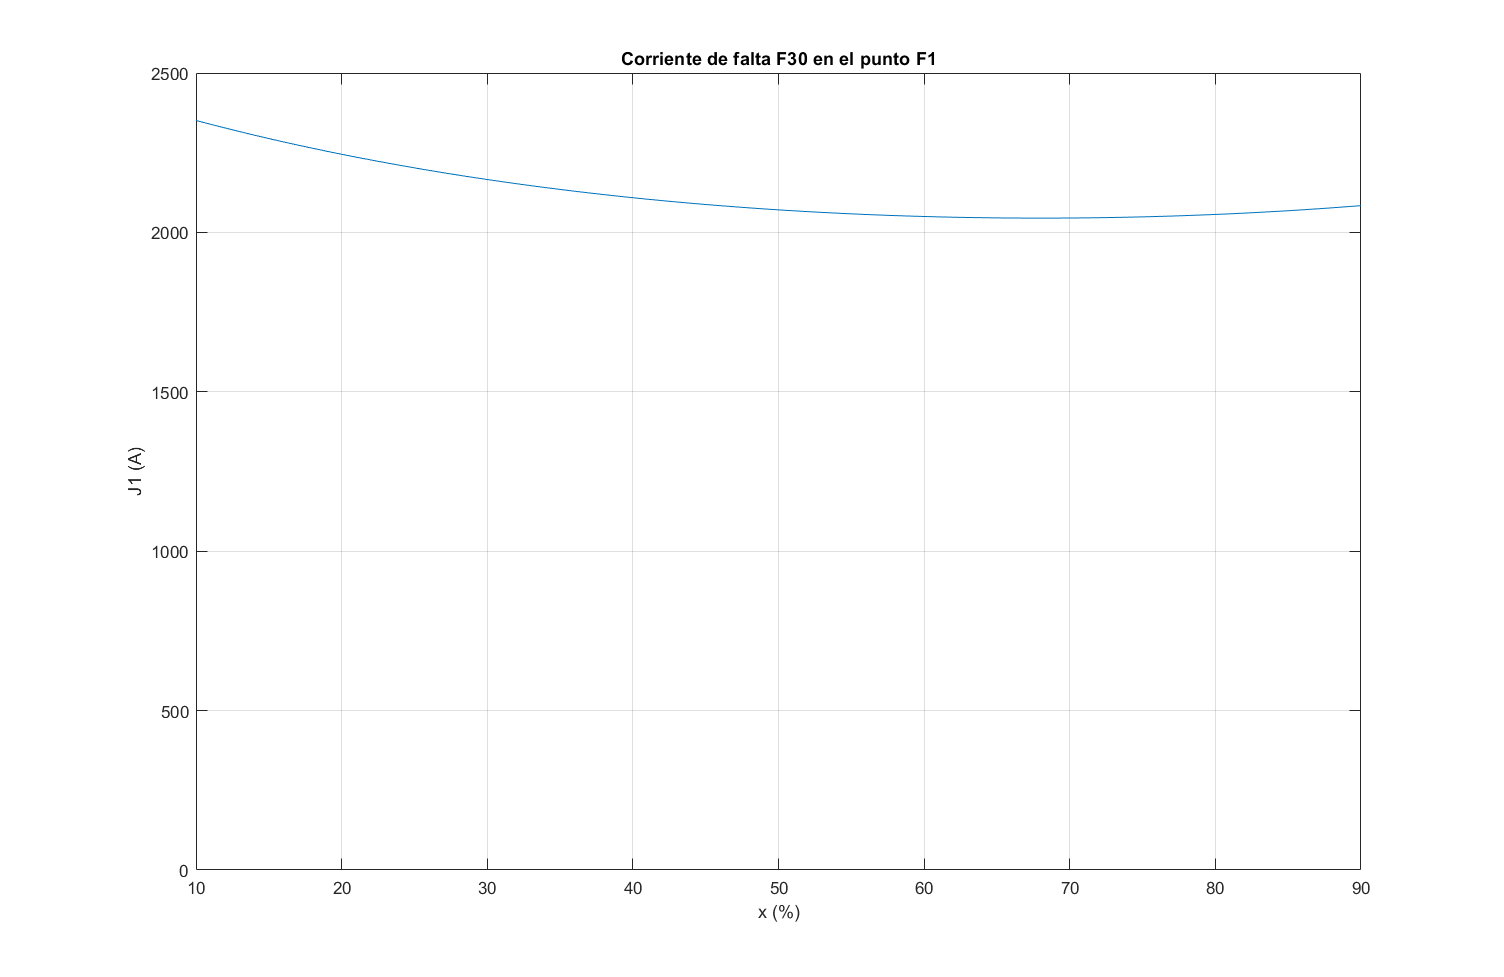


% Representación gráfica de la corriente de falta en función de x (en
% módulo)
xF1 = 10:90;
plot(xF1, abs(J1F1(xF1/100)));
title('Corriente de falta F30 en el punto F1');
xlabel('x (%)');
ylabel('J1 (A)');
grid on;
ylim([0, 2500]);